clear all
clf
DF = 100e3; %load range N
ai = 5; %intial crake size mm
t = 10; %tykkelse af plade mm
l = 100; %brede af plade mm
A_N = t*l %areal normalt på kraften

A_N =         1000


A  = 5.21e-13; % fra IIW
n  = 3.0;  % fra IIW

Vi finder stress range $\Delta$$\sigma$

DS_N = DF / A_N

DS_N =    100


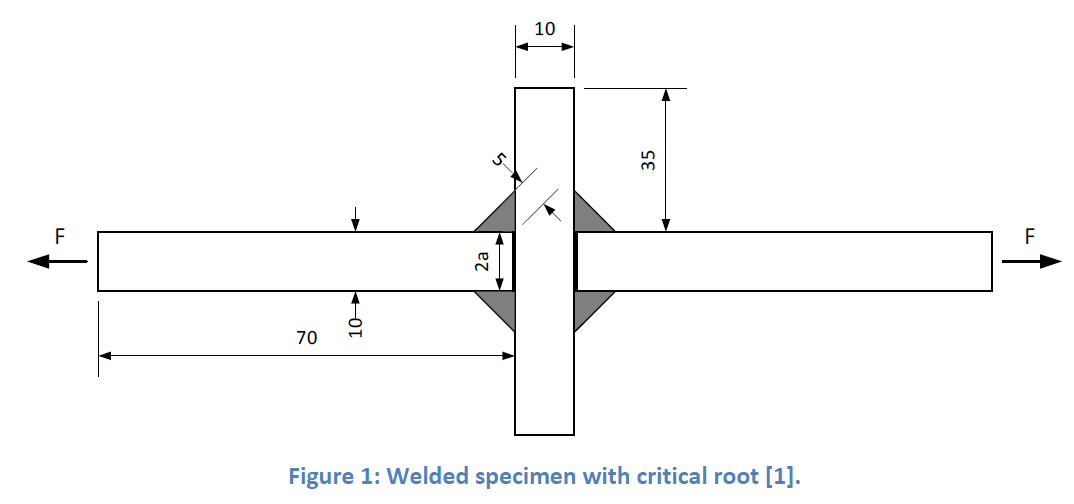

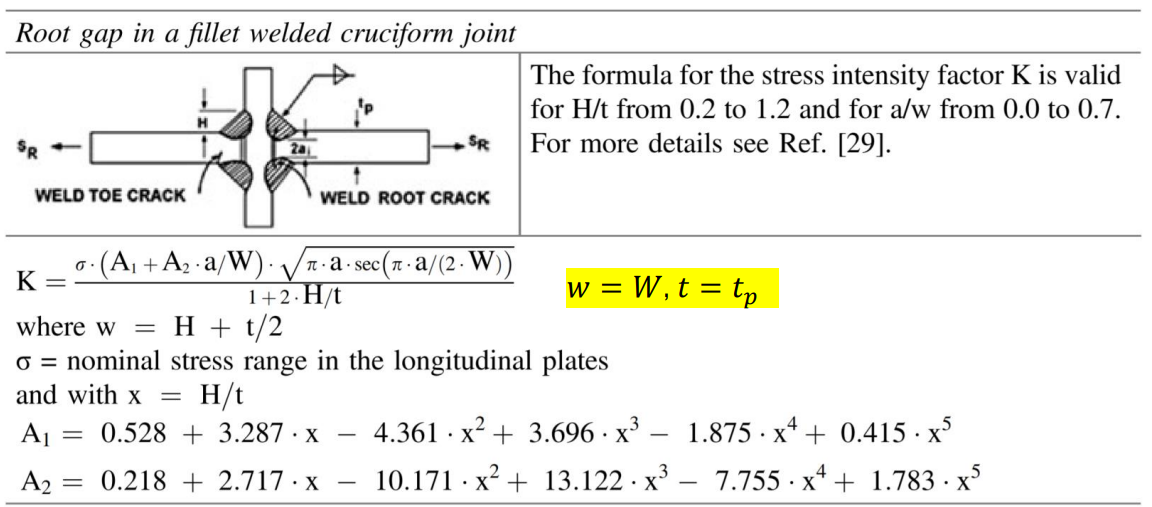

af = 12; % mm
N  = 0;
i  = 0;
a  = ai;
dN = 10; % cycle increments

Stress intensity factor range (SIF) for at få den i standard enheden $MPa\sqrt{mm}$ skal spændinger være i MPa og størrelser i mm

    

while a < af
    t = 10;
    H = sqrt(2)*ai;
    w = H + t/2;
    x = H/t;
    aw = a/w;

    % if (0 < aw && aw < 0.7) && (0.2 < x && x < 1.2) && i < 1e6
    %     % disp('duer')
    % else
    %     disp('duer IKKE')
    %     a
    %     i
    %     break
    % end

    A1 = 0.528 + 3.287*x - 4.361*x^2 + 3.696*x^3 - 1.875*x^4 + 0.415*x^5;
    A2 = 0.218 + 2.717*x -10.171*x^2 +13.122*x^3 - 7.755*x^4 + 1.783*x^5;

    dK = (DS_N*(A1+A2*a/w)*(pi*a*sec(pi*a/(2*w)))^(1/2))/(1+2*H/t);
    
    % forlængelse af sprækken
    da = dN * A*dK^n;
    
    % integrations delen
    a = a + da;
    N = N + dN;
    
    % plot værdier
    i = i + 1;
    ap(i) = a;
    Np(i) = N;   
    dKs(i) = dK;
    dadN(i) =  da/dN;
end

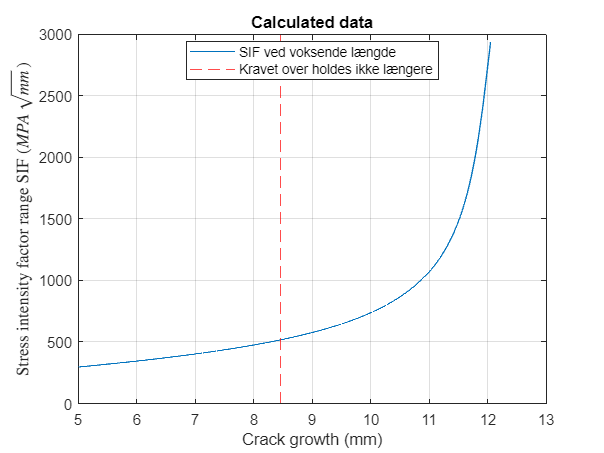

% length(dKs)
figure(1)
plot(ap,dKs, DisplayName='SIF ved voksende længde') %konverting from 
title('Calculated data')
xline(8.45,'r--', DisplayName='Kravet over holdes ikke længere')
xlabel('Crack growth (mm)')
ylabel('Stress intensity factor range SIF ($MPA\sqrt{mm}$)', Interpreter='latex')
legend(Location='best')
grid('on')

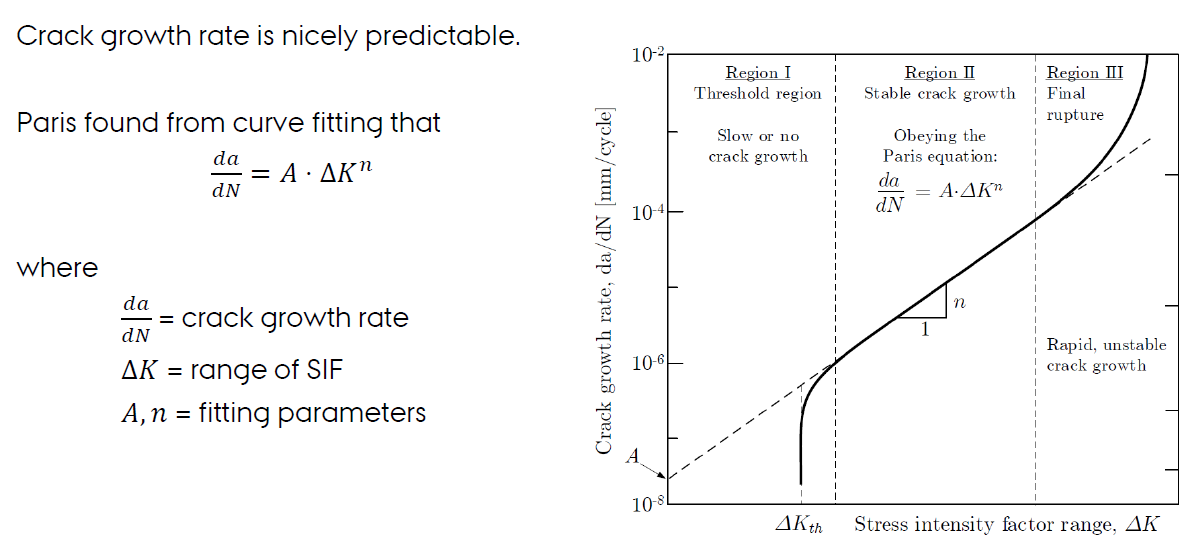

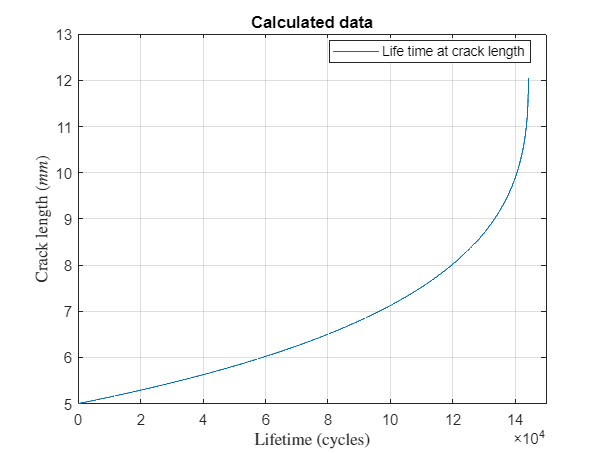


% Np
figure(2)
plot(Np,ap, DisplayName='Life time at crack length') %konverting from 
title('Calculated data')
ylabel('Crack length ($mm$)',Interpreter='latex')
xlabel('Lifetime (cycles)', Interpreter='latex')
xticks(0:2e4:14e4)
legend(Location='best')
grid('on')


N_life_end = Np(end)

N_life_end =       144220


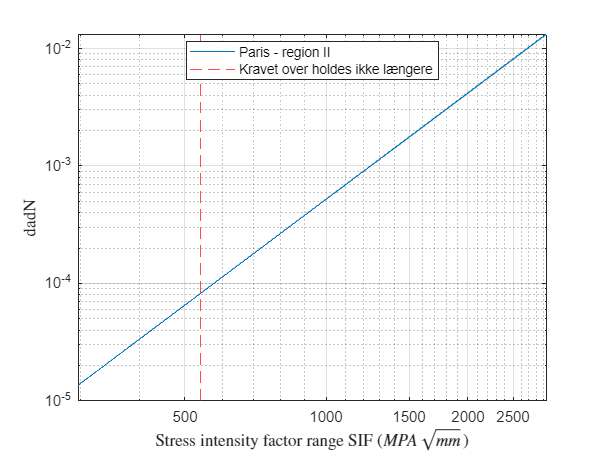


figure(3)
loglog(dKs,dadN, DisplayName='Paris - region II')
xline(540,'r--', DisplayName='Kravet over holdes ikke længere')
ylabel('dadN',Interpreter='latex')
xlabel('Stress intensity factor range SIF ($MPA\sqrt{mm}$)', Interpreter='latex')
legend(Location='best')
grid('on')

k_ansys = 300.27 %res 289

k_ansys =        300.27


k_calc = dKs(1)

k_calc =        296.65


% dK = k_ansys

% af = 10; % mm
% N  = 0;
% i  = 0;
% a  = ai;
% dN = 10; % cycle increments
% while a < af
%     t = 10;
%     H = sqrt(2)*ai;
%     w = H + t/2;
%     x = H/t;
%     aw = a/w;
% 
%     if (0 < aw && aw < 0.7) && (0.2 < x && x < 1.2) && i < 1e6
%         % disp('duer')
%     else
%         disp('duer IKKE')
%         a
%         i
%         break
%     end
% 
%     A1 = 0.528 + 3.287*x - 4.361*x^2 + 3.696*x^3 - 1.875*x^4 + 0.415*x^5;
%     A2 = 0.218 + 2.717*x -10.171*x^2 +13.122*x^3 - 7.755*x^4 + 1.783*x^5;
% 
% 
%     % forlængelse af sprækken
%     da = dN * A*dK^n;
% 
%     dK = (DS_N*(A1+A2*a/w)*(pi*a*sec(pi*a/(2*w)))^(1/2))/(1+2*H/t);
% 
% 
%     % integrations delen
%     a = a + da;
%     N = N + dN;
% 
%     % plot værdier
%     i = i + 1;
%     ap(i) = a;
%     Np(i) = N;   
%     dKs(i) = dK;
%     dadN(i) =  da/dN;
% end
% N_life_end = Np(end)


% figure(4)
% plot(Np,ap, DisplayName='Life time at crack length') %konverting from 
% title('Calculated data')
% ylabel('Crack length ($mm$)',Interpreter='latex')
% xlabel('Lifetime (cycles)', Interpreter='latex')
% xticks(0:2e4:14e4)
% legend(Location='best')
% grid('on')

% plot(a, N)